# Laboratory nr 3 - aerial robotics

## Task nr 3 - trajectories

## square trajectory

clear

function [x_d, y_d, z_d, yaw_d] = square_trajectory(x_c, y_c, z_c, yaw_c, offsets)

    persistent idx
    if isempty(idx)
        idx = 1;
        
        
    end
    
    % x, y, z, yaw, notation
    traject = [1, 3, 1, 0;
        1, 3, 1, pi/2;
        1, 5, 1, pi/2;
        1, 5, 1, pi;
        -1, 5, 1, pi;
        -1, 5, 1, -pi/2;
        -1, 3, 1, -pi/2;
        -1, 3, 1, 0];

    pt = traject(idx, :);
    x_d = pt(1);
    y_d = pt(2);
    z_d = pt(3);
    yaw_d = pt(4);

    if (abs(x_d-x_c) < offsets(1)) && (abs(y_d-y_c) < offsets(2)) && (abs(z_d - z_c) < offsets(3)) && (abs(wrapToPi(yaw_d - yaw_c)) < offsets(4))
        idx = idx + 1;
        if idx > size(traject, 1)
            idx = 1;
        end
    end


end

## circular trajectory with drone heading towards center of the circle

function [x_d, y_d, z_d, yaw_d] = circular_trajectory(x_c, y_c, z_c, yaw_c, offsets)

    persistent idx
    if isempty(idx)
        idx = 1;
    
    
    end
    N = 20;
    radius = 0.5;
    y_offset = 4;
    angles = linspace(0, 2*pi, N)';
    x = cos(angles) * radius;
    y = sin(angles) * radius;
    
    
    yaw = wrapToPi(angles - pi);
    z = ones(1, N)';
    
    % x, y, z, yaw, notation
    traject = [x, y + y_offset, z, yaw];
    
    pt = traject(idx, :);
    x_d = pt(1);
    y_d = pt(2);
    z_d = pt(3);
    yaw_d = pt(4);
    
    if (abs(x_d-x_c) < offsets(1)) && (abs(y_d-y_c) < offsets(2)) && (abs(z_d - z_c) < offsets(3)) && (abs(wrapToPi(yaw_d - yaw_c)) < offsets(4))
        idx = idx + 1;
        if idx > size(traject, 1)
            idx = 1;
        end
    end


end

## circle rotated

function [x_d, y_d, z_d, yaw_d] = circular_rotated(x_c, y_c, z_c, yaw_c, offsets)

persistent idx
if isempty(idx)
    idx = 1;


end
N = 20;
radius = 0.5;
cx = 0; cy = 4; cz = 1;
angles = linspace(0, 2*pi, N)';
x = cos(angles) * radius;
y = sin(angles) * radius;

z = zeros(1, N)';

% x, y, z, yaw, notation
inclination = roty(45, 'deg'); % creating rotation matrix here
% inclination matrix if the above not working
% th = 45*pi/180;
% inclination = [ cos(th) 0 sin(th);
%     0       1 0;
%     -sin(th) 0 cos(th)];
traject = [x, y, z];
traject = traject*inclination.';

traject(:,1) = traject(:,1) + cx;
traject(:,2) = traject(:,2) + cy;
traject(:,3) = traject(:,3) + cz;
yaw = atan2(cy - traject(:,2), cx - traject(:,1));
traject = [traject, yaw];

pt = traject(idx, :);
x_d = pt(1);
y_d = pt(2);
z_d = pt(3);
yaw_d = pt(4);

if (abs(x_d-x_c) < offsets(1)) && (abs(y_d-y_c) < offsets(2)) && (abs(z_d - z_c) < offsets(3)) && (abs(wrapToPi(yaw_d - yaw_c)) < offsets(4))
    idx = idx + 1;
    if idx > size(traject, 1)
        idx = 1;
    end
end


end

## some tests

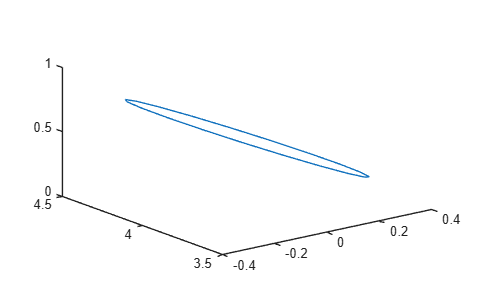

N = 20;
radius = 0.5;
cx = 0; cy = 4; cz = 0.5;
angles = linspace(0, 2*pi, N)';
x = cos(angles) * radius;
y = sin(angles) * radius;


z = zeros(1, N)';

% x, y, z, yaw, notation
inclination = roty(45, 'deg'); % creating rotation matrix here
traject = [x, y, z];
traject = traject*inclination.';

traject(:,1) = traject(:,1) + cx;
traject(:,2) = traject(:,2) + cy;
traject(:,3) = traject(:,3) + cz;
yaw = atan2(cy - traject(:,2), cx - traject(:,1));
traject = [traject, yaw];
plot3(traject(:,1), traject(:,2), traject(:,3))

## collision avoidance

function [x_d, y_d, z_d, yaw_d] = collision_aviodance(v_c, v_a, ri, L)

    persistent ref def_yaw
    if isempty(ref)
        ref = [0 4 1];
        def_yaw = 0;
    end
    
    v_c = v_c(:)';
    v_a = v_a(:)';
    d = v_c - v_a;
    no = norm(d);
    
    dpref = [0, 0, 0];
    if (0 < no) && (no < ri)
        dpref = L*(1-no/ri)*((d)/no);
        
    end

    p_d = ref + dpref;

    x_d = p_d(1);
    y_d = p_d(2);
    z_d = p_d(3);
    yaw_d = def_yaw;
end